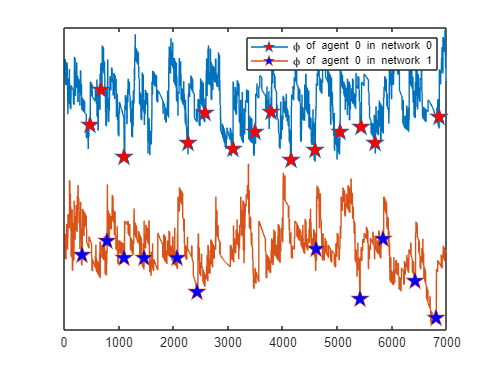

D = csvread("output_phi_log.txt");

totalSteps = size(D,1);
phi0 = D(13:totalSteps,1);
phi1 = D(13:totalSteps,3);
t = (13:totalSteps)';

len_t = length(t);

expell_0 = find(D(13:totalSteps,2) == 1) - 1;
expell_1 = find(D(13:totalSteps,4) == 1) - 1;


plot(t,phi0-7,'-p','MarkerIndices',expell_0,...
    'MarkerFaceColor','red',...
    'MarkerSize',15)
hold on

plot(t,phi1,'-p','MarkerIndices',expell_1,...
    'MarkerFaceColor','blue',...
    'MarkerSize',15)
xlim([0,7001])
set(gca, 'YTick', [])

legend("\phi of agent 0 in network 0", "\phi of agent 0 in network 1")
hold off